addpath('./functions');
addpath('./data');

load('bignet.mat')
load('ood_detection.mat')
[XTrain, YTrain, XTest, YTest] = load_data('data');

% analyzeNetwork(bignet)

layer = "fc_4096b"

layer = "bn_8"

% trainFeatures = activations(bignet, XTrain, layer, OutputAs="rows")
[X_train, X_test, Y_train, Y_test] = train_test_split(ood_detection.data, ood_detection.labels, 0.2);
featuresTrain = activations(bignet, X_train, layer, OutputAs="rows");
featuresTest = activations(bignet, X_test, layer, OutputAs="rows");

mdl = fitcecoc(featuresTrain,Y_train);

% validationFeatures = activations(bignet, XTest, layer, OutputAs="rows");

Ypred = predict(mdl, featuresTest);
tp = nnz(Ypred == Y_test);
accuracy = tp / length(Y_test);
disp(['The network achieved an accuracy of: ', num2str((accuracy)*100), '%'])

The network achieved an accuracy of: 97.5%


% histogram(trainFeatures)

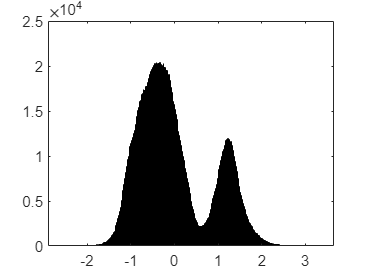

histogram(featuresTrain)

% [Mdl, tf, scores] = iforest(trainFeatures,"CategoricalPredictors","all")
% histogram(scores)
% xline(Mdl.ScoreThreshold,"r-",["Threshold" Mdl.ScoreThreshold])

% [tf_test,s_test] = isanomaly(Mdl, testFeatures)

% histogram(scores,Normalization="probability")
% hold on
% histogram(s_test,Normalization="probability")
% xline(Mdl.ScoreThreshold,"r-",join(["Threshold" Mdl.ScoreThreshold]))
% legend("Training Data","Test Data",Location="northwest")
% hold off

% s_test

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.03375 |     0.76122 |     0.03375 |     0.03375 |       100.51 |     0.019679 |
|    2 | Accept |     0.03375 |     0.59138 |     0.03375 |     0.03375 |    0.0035299 |     0.026978 |
|    3 | Accept |     0.61875 |      27.316 |     0.03375 |    0.033602 |       452.12 |       534.53 |
|    4 | Accept |      0.4925 |      1.0511 |     0.03375 |    0.033768 |      0.27876 |        366.6 |
|    5 | Accept |     0.03375 |     0.49187 |     0.03375 |    0.033175 |       6.3841 |      0.13776 |
|    6 | Accept |      0.5425 |      41.798 |     0.03375 |    0

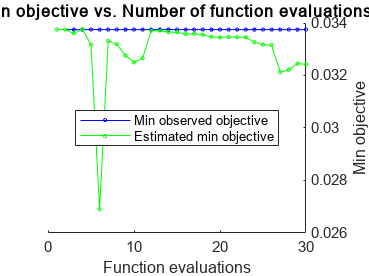

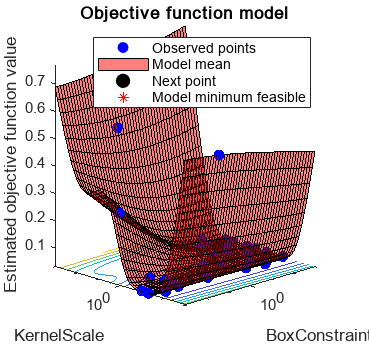


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 158.9572 seconds
Total objective function evaluation time: 139.3785

Best observed feasible point:
    BoxConstraint    KernelScale
    _____________    ___________

       100.51         0.019679  

Observed objective function value = 0.03375
Estimated objective function value = 0.034067
Function evaluation time = 0.76122

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale
    _____________    ___________

       203.41          12.154   

Estimated objective function value = 0.032426
Estimated function evaluation time = 2.6845



Mdl =   ClassificationSVM
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [id    ood]
                       ScoreTransform: 'none'
                      NumObservations: 800
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                                Alpha: [202×1 single]
                                 Bias: 0.0585
                     KernelParameters: [1×1 struct]
                       BoxConstraints: [800×1 single]
                      ConvergenceInfo: [1×1 struct]
                      IsSupportVector: [800×1 logical]
                               Solver: 'SMO'


  Properties, Methods


rng default
Mdl = fitcsvm(featuresTrain,Y_train,'OptimizeHyperparameters','auto', ...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName', ...
    'expected-improvement-plus'))

Ypred = predict(Mdl, featuresTest);
tp = nnz(Ypred == Y_test);
accuracy = tp / length(Y_test);
disp(['The network achieved an accuracy of: ', num2str((accuracy)*100), '%'])

The network achieved an accuracy of: 97.5%


The network achieved an accuracy of: 0%


layer = "fc_4096b"

layer = "fc_4096b"

featuresTrain = activations(bignet, XTrain, layer, OutputAs="rows");
[Mdl, tf, s] = iforest(featuresTrain,"ContaminationFraction",0.2);
Mdl.ScoreThreshold

ans = single
0.4454

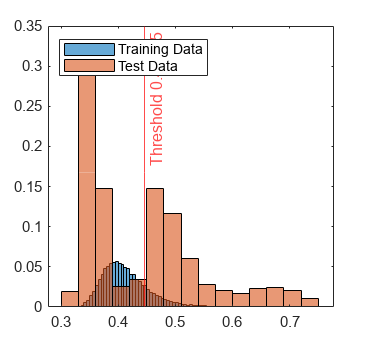

featuresTest = activations(bignet, ood_detection.data, layer, OutputAs="rows");
[tf_test,s_test] = isanomaly(Mdl,featuresTest);


histogram(s,Normalization="probability")
hold on
histogram(s_test,Normalization="probability")
xline(Mdl.ScoreThreshold,"r-",join(["Threshold" Mdl.ScoreThreshold]))
legend("Training Data","Test Data",Location="northwest")
hold off

ans = 0.4750

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

layer = "fc_4096b"

layer = "fc_4096b"


featuresTrain = activations(bignet, XTest, layer, OutputAs="rows");
featuresTest = activations(bignet, ood_detection.data, layer, OutputAs="rows");
contaminationFraction = single(0.2);
W = ones(size(featuresTrain, 1), 1);
% Perform the one-class SVM using fitcsvm function
mdl = fitcsvm(featuresTrain, W, 'KernelScale', 'auto', 'Standardize', false, 'OutlierFraction', 0.04,'KernelFunction','gaussian');
[~, scoreValid] = predict(mdl, featuresTest);
YpredValid=scoreValid<0;
Ypred = zeros(size(YpredValid,1),1);
Ypred(YpredValid) = 'ood';
Ypred(~YpredValid) = 'id';
Ypred = categorical(Ypred);

tp = nnz(Ypred == ood_detection.labels);
accuracy = tp / length(ood_detection.labels);
disp(['The network achieved an accuracy of: ', num2str((accuracy)*100), '%'])